clear all;
clc;

disp("Independent work 06 - interpolation 01.");

Independent work 06 - interpolation 01.



%% Question 1
disp("Question 01.");

Question 01.



% Given data
x1 = [10, 12, 14, 16];
fx1 = [0.98481, 0.97815, 0.97030, 0.96126];

% Constructing the Vandermonde matrix
A1 = [1 10 100 1000;
     1 12 144 1728;
     1 14 196 2744;
     1 16 256 4096];
 
% Right-hand side vector
B1 = [0.98481; 0.97815; 0.97030; 0.96126];

% Solving for coefficients
X1 = A1\B1;

% Coefficients
a0_1 = X1(1);
a1_1 = X1(2);
a2_1 = X1(3);
a3_1 = X1(4);

% Displaying coefficients
disp('Coefficients:');

Coefficients:


disp('      a0,     a1,     a2,     a3 ');

      a0,     a1,     a2,     a3 


disp(X1');

    1.0003   -0.0001   -0.0001   -0.0000




% Cubic polynomial
syms x1_sym;
P3_1 = a0_1 + a1_1*x1_sym + a2_1*x1_sym^2 + a3_1*x1_sym^3;

% Plotting data points
x1v = [10 12 14 16];
y1v = [0.98481 0.97815 0.97030 0.96126];
figure;
plot(x1v, y1v, '*r');
hold on;

% Plotting interpolating polynomial
x1x = linspace(10, 16, 100);
plot(x1x, double(subs(P3_1, x1x)), '-b');

% Estimating values
x1_estimate = [12.75, 13.5];
y1_estimate = double(subs(P3_1, x1_estimate));
disp('Estimated values:');

Estimated values:


disp('      x1,     y1  ');

      x1,     y1  


disp([x1_estimate; y1_estimate]);

   12.7500   13.5000
    0.9753    0.9724




% Comparing with true values
true_values_1 = cosd(x1_estimate);
disp('True values:');

True values:


disp('      x1,     y1  ');

      x1,     y1  


disp(true_values_1);

    0.9753    0.9724



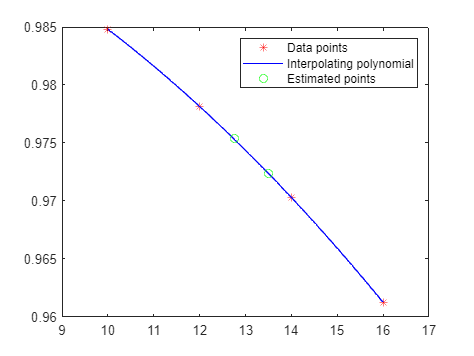


% Adding estimated points to the plot
plot(x1_estimate, y1_estimate, 'og');
legend('Data points', 'Interpolating polynomial', 'Estimated points');
xlim([9 17]);
hold off;


%% Question 2
disp("Question 02.");

Question 02.



% Given data
x2 = [-2, -1, 1.5, 3];
y2 = [0.4042, 0.4714, 0.4400, 0.3681];

% Lagrangian Polynomial
syms x2_sym;
L0_2 = ((x2_sym - x2(2)) * (x2_sym - x2(3)) * (x2_sym - x2(4))) / ((x2(1) - x2(2)) * (x2(1) - x2(3)) * (x2(1) - x2(4)));
L1_2 = ((x2_sym - x2(1)) * (x2_sym - x2(3)) * (x2_sym - x2(4))) / ((x2(2) - x2(1)) * (x2(2) - x2(3)) * (x2(2) - x2(4)));
L2_2 = ((x2_sym - x2(1)) * (x2_sym - x2(2)) * (x2_sym - x2(4))) / ((x2(3) - x2(1)) * (x2(3) - x2(2)) * (x2(3) - x2(4)));
L3_2 = ((x2_sym - x2(1)) * (x2_sym - x2(2)) * (x2_sym - x2(3))) / ((x2(4) - x2(1)) * (x2(4) - x2(2)) * (x2(4) - x2(3)));

P3_2 = y2(1)*L0_2 + y2(2)*L1_2 + y2(3)*L2_2 + y2(4)*L3_2;

% Determining the value at x = 2.3
x2_query = 2.3;
P3_2_value = double(subs(P3_2, x2_query));
disp(['P_3(2.3) = ', num2str(P3_2_value)]);

P_3(2.3) = 0.40145


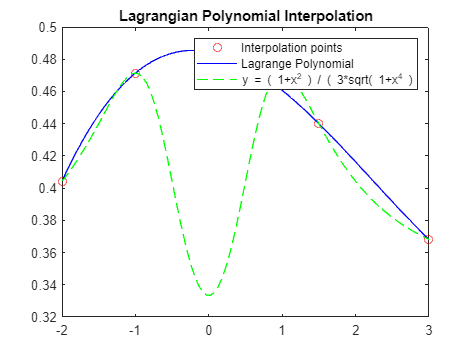


% Plotting the Lagrange polynomial and interpolation points
f2 = @(x) (1 + x.^2) ./ (3 .* sqrt(1 + x.^4));
x2_plot = linspace(-2, 3, 100);

figure;
plot(x2, y2, 'or'); % Interpolation points
hold on;
plot(x2_plot, double(subs(P3_2, x2_plot)), '-b'); % Lagrange polynomial
plot(x2_plot, f2(x2_plot), '--g'); % Given function
legend('Interpolation points', 'Lagrange Polynomial', 'y = ( 1+x^2 ) / ( 3*sqrt( 1+x^4 )');
title('Lagrangian Polynomial Interpolation');
hold off;


%% Question 3
disp("Question 03.");

Question 03.


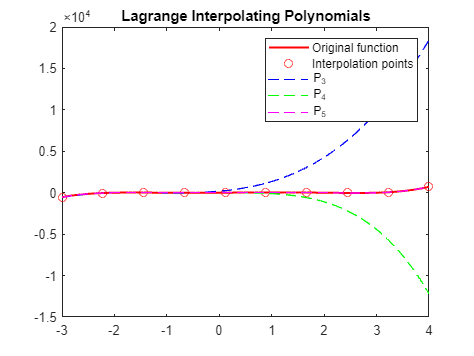


% Given polynomial
f3 = @(x) 3*x.^5 - 6*x.^4 - 21*x.^3 + 24*x.^2 + 36*x;

% Interval
x3 = linspace(-3, 4, 100);

% Interpolation points
n3 = 10; % Number of points
x3_interp = linspace(-3, 4, n3);
y3_interp = f3(x3_interp);

% Lagrange interpolating polynomials P3, P4, P5
syms x3_sym;
P3_3 = lagrange_interpolation(x3_interp(1:4), y3_interp(1:4), x3_sym);
P4_3 = lagrange_interpolation(x3_interp(1:5), y3_interp(1:5), x3_sym);
P5_3 = lagrange_interpolation(x3_interp(1:6), y3_interp(1:6), x3_sym);

% Plotting
figure;
plot(x3, f3(x3), '-r', 'LineWidth', 1.5); % Original function
hold on;
plot(x3_interp, y3_interp, 'or'); % Interpolation points
fplot(matlabFunction(P3_3), [-3, 4], '--b'); % P3
fplot(matlabFunction(P4_3), [-3, 4], '--g'); % P4
fplot(matlabFunction(P5_3), [-3, 4], '--m'); % P5
legend('Original function', 'Interpolation points', 'P_3', 'P_4', 'P_5');
title('Lagrange Interpolating Polynomials');
hold off;


% Function to compute Lagrange interpolating polynomial

function P = lagrange_interpolation(x, y, x_sym)
    n = length(x);
    P = 0;
    for k = 1:n
        Lk = 1;
        for j = [1:k-1, k+1:n]
            Lk = Lk * (x_sym - x(j)) / (x(k) - x(j));
        end
        P = P + y(k) * Lk;
    end
end
